# Lab 7-8

For this lab, I chose the high pt signal (pt = 1000-1200). In this lab I will be exploring different variables in the Higgs and QCD data set.

**Section 1**

In this section, I am looking to the mass variable of the Higgs and QCD data set. I first import the data and store the Higgs data and QCD data into two different matrices.

clear all
close all
clc

h5disp('higgs_100000_pt_1000_1200.h5')

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


higgs = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
h5disp('qcd_100000_pt_1000_1200.h5')

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


qcd = h5read('qcd_100000_pt_1000_1200.h5','/qcd_100000_pt_1000_1200');


After I import the data, I plet the mass of both Higgs data and QCD data. I stacked two histograms together and see what do the distribution look like. 

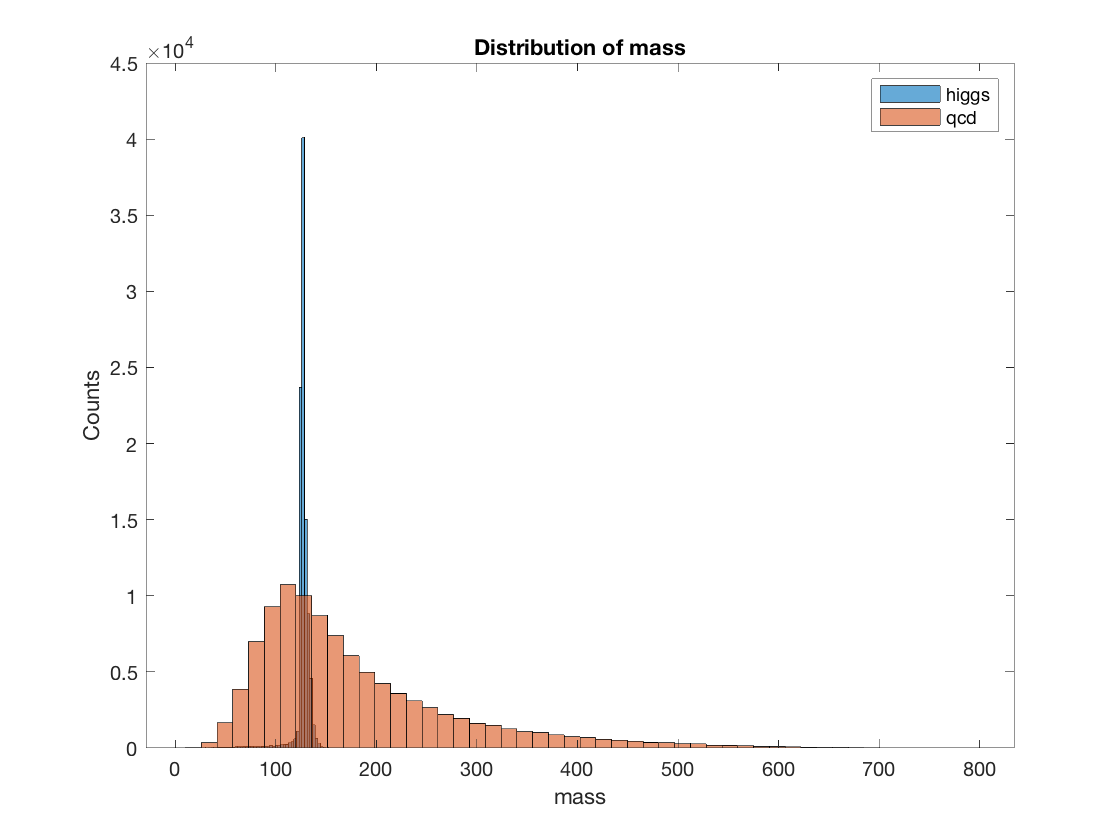

%plotmass of higgs and qcd data
mass_higgs = higgs(4,:);
mass_qcd = qcd(4,:);

histogram(higgs(4,:),50)
hold on
histogram(qcd(4,:),50)
legend('higgs','qcd')
title('Distribution of mass')
ylabel('Counts')
xlabel('mass')
hold off

After I made plot, I then fit the mass distribution from the QCD data with a Poisson distribution. Once the distribution of the mass from QCD is found, I then try to find the significance of the signal. In this context, signal is the mass from the Higgs data. The distribution of the higgs mass data seem to center around 125. The mass of the Higgs boson is 125 Gev, which matches the value that the higgs mass center around. Here, I am going to take the signal as 125 and use that value to find the significance.

pd = fitdist(mass_qcd','Poisson');
signal = 125;
lambda = 177.273

lambda = 177.2730

P = cdf('Poisson',signal,115);
sigma = icdf('Normal',P,0,1);

When I am fitting the QCD mass data with the Poisson distribution, I get a lambda of 177. It seems too high compared to what we see on the histogram. Instead of using matlab function to fit the distribution, I am going to eyeball where the distribution center around and use that value as lambda. In the end, I chose 115 as the lambda of the Poisson distribution.

To find the significance of the signal, I evaluated the math equations below:

P = $\int_{125}^{\infty } \left\lbrack {p\left(x\right)}_{\mathrm{poisson}} \right\rbrack \mathrm{dx}$

P = $\int_{-\infty }^X \left\lbrack {p\left(x\right)}_{\mathrm{Gaussian}} \right\rbrack \mathrm{dx}$, Solve for X.

The above mathematic equations first find the probability of the background giving us a signal that is equal to or higher than 125. The second equation is finding the sigma associated the probability found by the first equation assuming the distribution is Gaussian.

In the end, sigma is found to be 0.98.

N_higgs = 50;
N_qcd = 2000;
N_r = N_higgs/sqrt(N_qcd);

N_higgs = 50 and N_qcd = 2000. And N_higgs/sqrt(N_qcd) = 1.118. This value is very close to 1, which means $N_{\mathrm{Higgs}} \approx \sqrt{N_{\mathrm{qcd}} }$

**Section 2**

In this section I am going to cut some data from the QCD mass data to optimize the significance of our signal. I will try various different ways to cut the data.

When we are optimizing the significance of the signal, we are basically maximize the ratio: $\frac{N_{\mathrm{Higgs}} }{\sqrt{N_{\mathrm{qcd}} }}$. The ratio of numbers of Higgs data to the square root of QCD data. We want to cut our data in ta way that this ratio if optimized because it means that we included most of the Higgs data while throwing away most of the QCD data, the background. 

$N_{\mathrm{Higgs}} \;\mathrm{and}\;N_{\mathrm{qcd}} \;\mathrm{are}\;\mathrm{calculated}\;\mathrm{as}\;\mathrm{follow}$:


$$\begin{array}{l}
N_{\mathrm{Higgs}} =50*\int_{125-x}^{125+x} P_{\mathrm{Higgs}} \left(x\right)\mathrm{dx}\\
N_{\mathrm{qcd}} =2000*\int_{125-x}^{125+x} P_{\mathrm{qcd}} \left(x\right)\mathrm{dx}
\end{array}$$


Since we know that Higgs data has a distribution center around 125, I will cut the data that is some distance away from 125 and cut the QCD data in the same way. The ratio of $N_{\mathrm{Higgs}} \;\mathrm{and}\;N_{\mathrm{qcd}}$ before cutting is 50 to 2000. For every 2000 QCD data, there are 50 Higgs. When we calculate the ratio after cutting, we calculate the probability of Higgs data being inside the section of the data that we keep and multiply the probability with 50 to find out how many of the 50 Higgs data points were kept. Then we calculate the probability of the QCD data being inside the section of data that we keep and multiple the probability by 2000. These two steps will give us $N_{\mathrm{Higgs}} \;\mathrm{and}\;N_{\mathrm{qcd}}$. After calculating $N_{\mathrm{Higgs}} \;\mathrm{and}\;N_{\mathrm{qcd}}$ we can take the ratio. 

Note: The section of the data we keep is: signal value = [125-x,125+x]. Where x is the parameter that we manipulate to optimize the ratio of $N_{\mathrm{Higgs}} \;\mathrm{to}\;N_{\mathrm{qcd}}$.

The code below use iterative method to find the parameter x that optimize the ratio. 

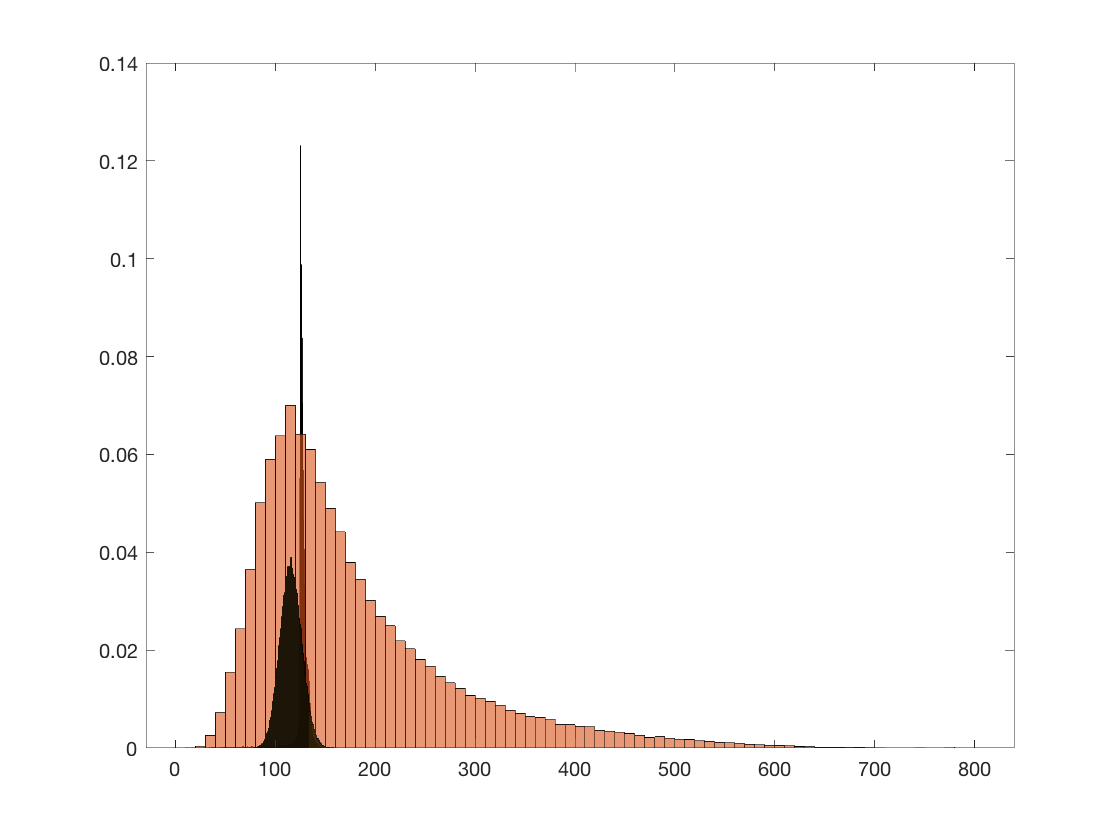

histogram(mass_higgs,'Normalization','probability')
hold on
histogram(mass_qcd,'Normalization','probability')
histogram(fit,'Normalization','probability')
hold off

pd_qcd = makedist('Poisson',115);
pd_higgs = makedist('Poisson',125);

fit = poissrnd(115,1,100000);
fun = @(t) -1*(50*(cdf(pd_higgs,125+t)-cdf(pd_higgs,125-t)))/sqrt(2000*(cdf(pd_qcd,125+t)-cdf(pd_qcd,125-t)));

ratio = fun(1);
for t =2:100
    
    diff = abs(fun(t)-ratio);
    ratio = fun(t);
    if diff<=0.001
        cut = t;
        break
    end
end


In the end, x is found to be 19, Which means we throw away the data that has a signal value smaller than 125-19 or greater than 125+19 in both QCD data and Higgs data. When we cut the data this way, the ratio : $\frac{N_{\mathrm{Higgs}} }{\sqrt{N_{\mathrm{qcd}} }}$ is optimized.

## Problem 3

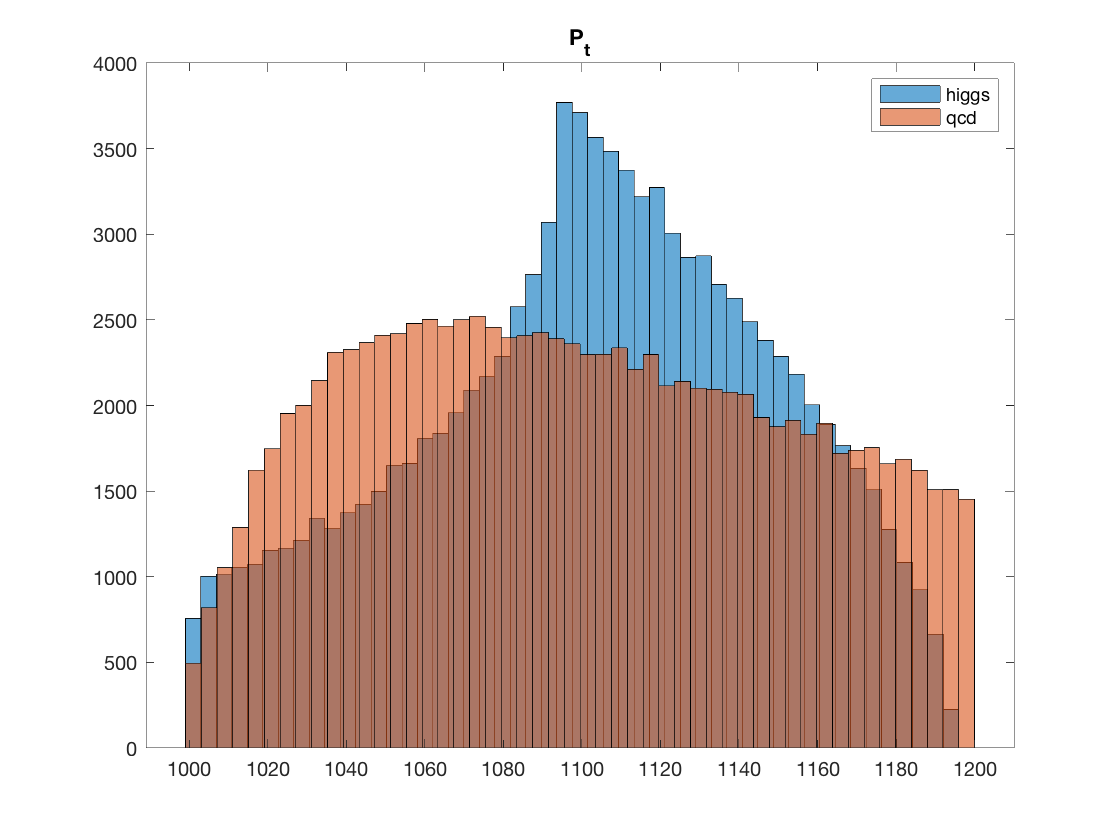


histogram(higgs(1,:),50)
hold on
histogram(qcd(1,:),50)
hold off
title('P_{t}')
legend('higgs','qcd')

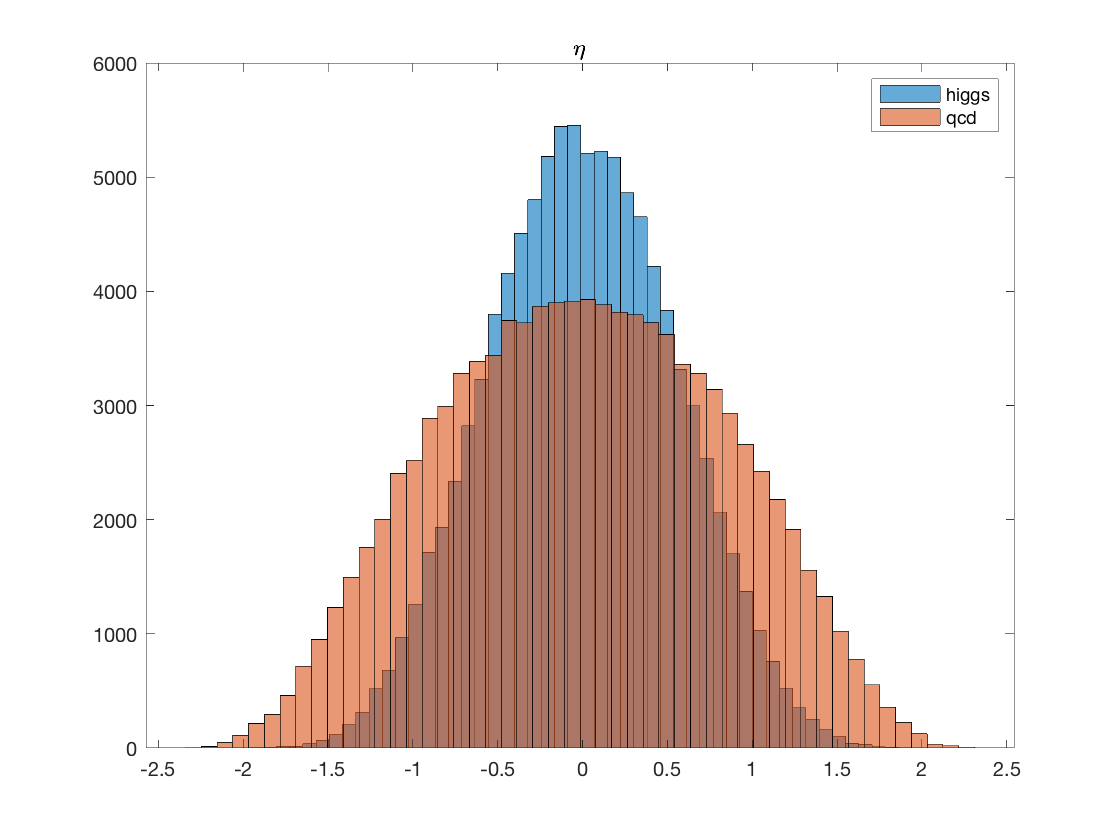

histogram(higgs(2,:),50)
hold on
histogram(qcd(2,:),50)
hold off
title('\eta')
legend('higgs','qcd')

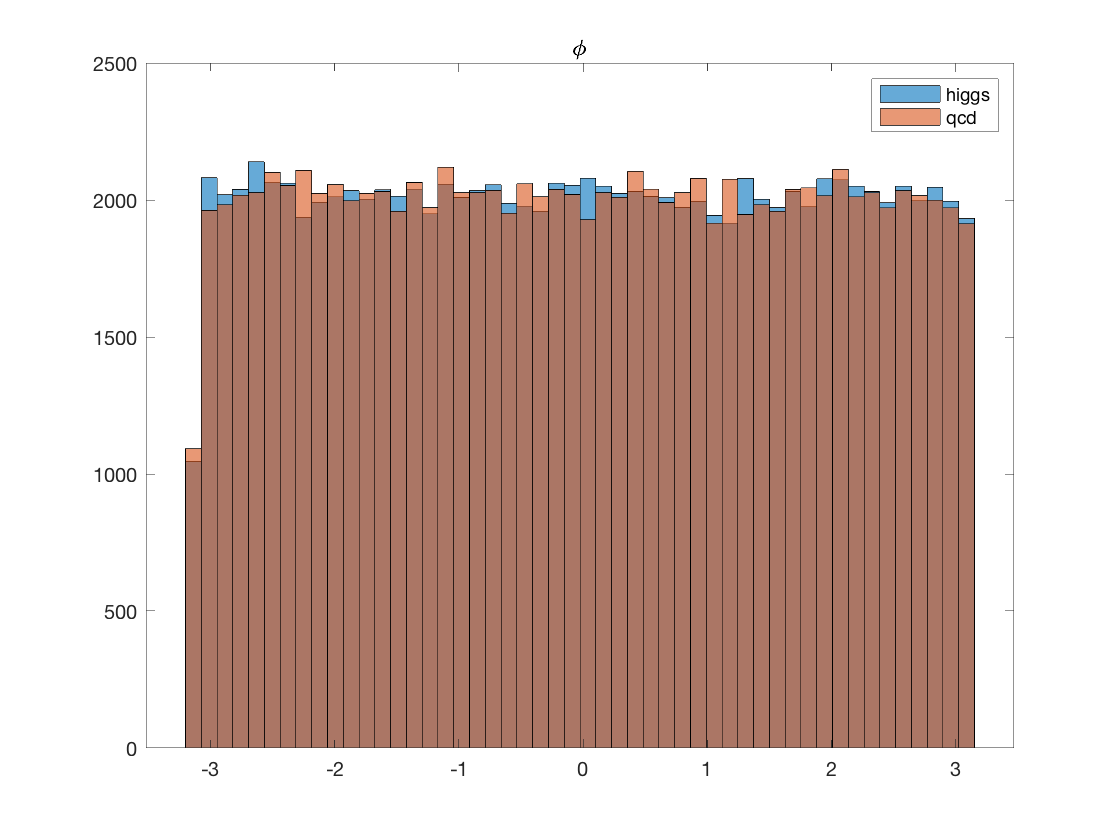

histogram(higgs(3,:),50)
hold on
histogram(qcd(3,:),50)
hold off
title('\phi')
legend('higgs','qcd')

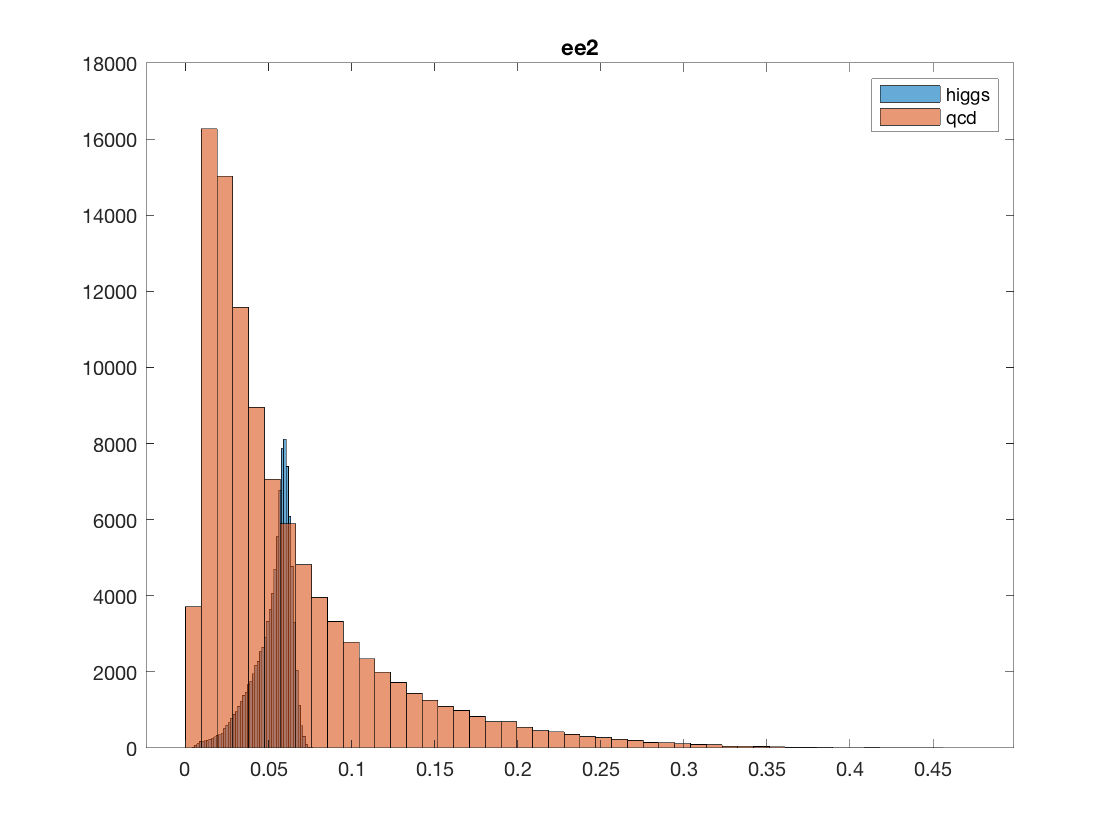

histogram(higgs(5,:),50)
hold on
histogram(qcd(5,:),50)
hold off
title('ee2')
legend('higgs','qcd')

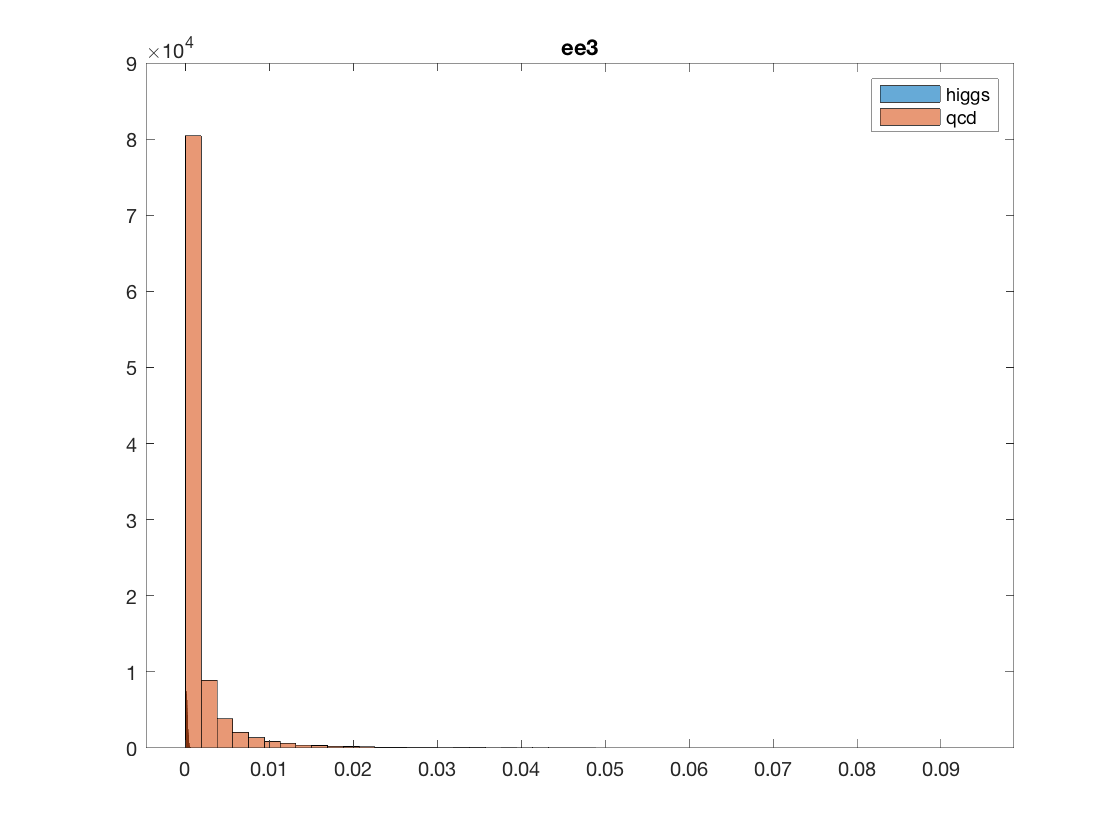

histogram(higgs(6,:),50)
hold on
histogram(qcd(6,:),50)
hold off
title('ee3')
legend('higgs','qcd')

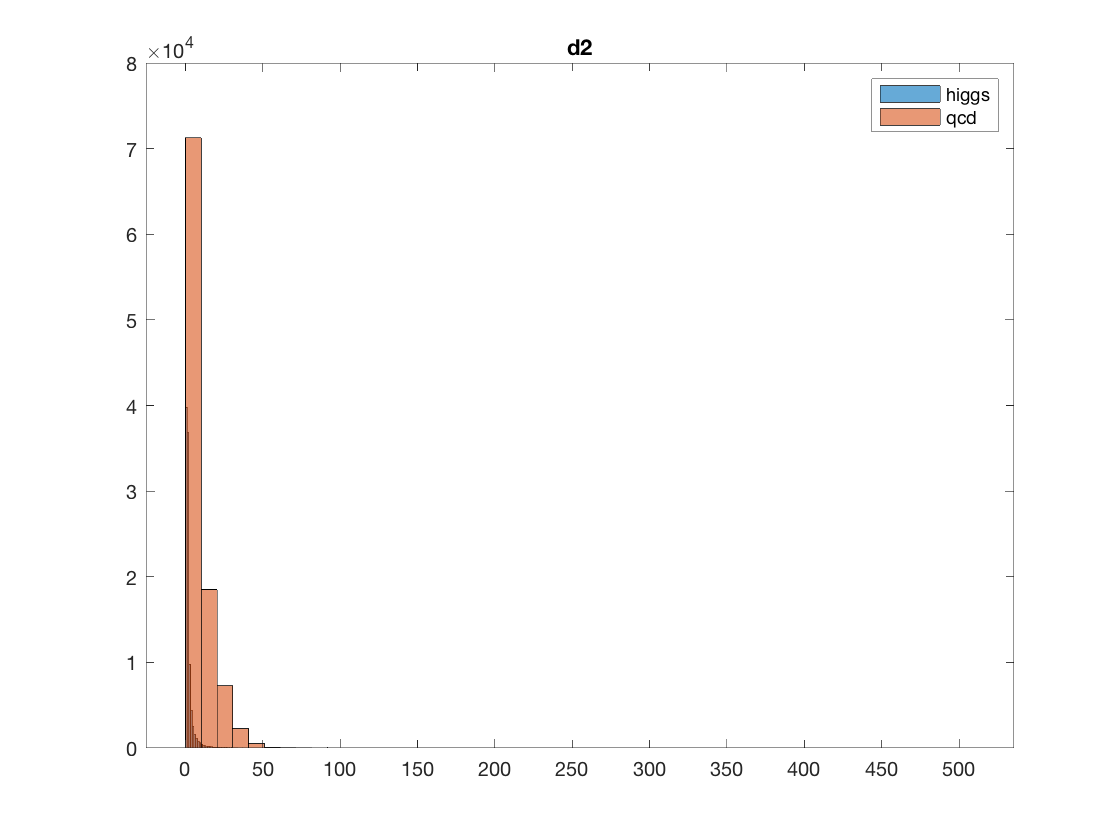

histogram(higgs(7,:),50)
hold on
histogram(qcd(7,:),50)
hold off
title('d2')
legend('higgs','qcd')

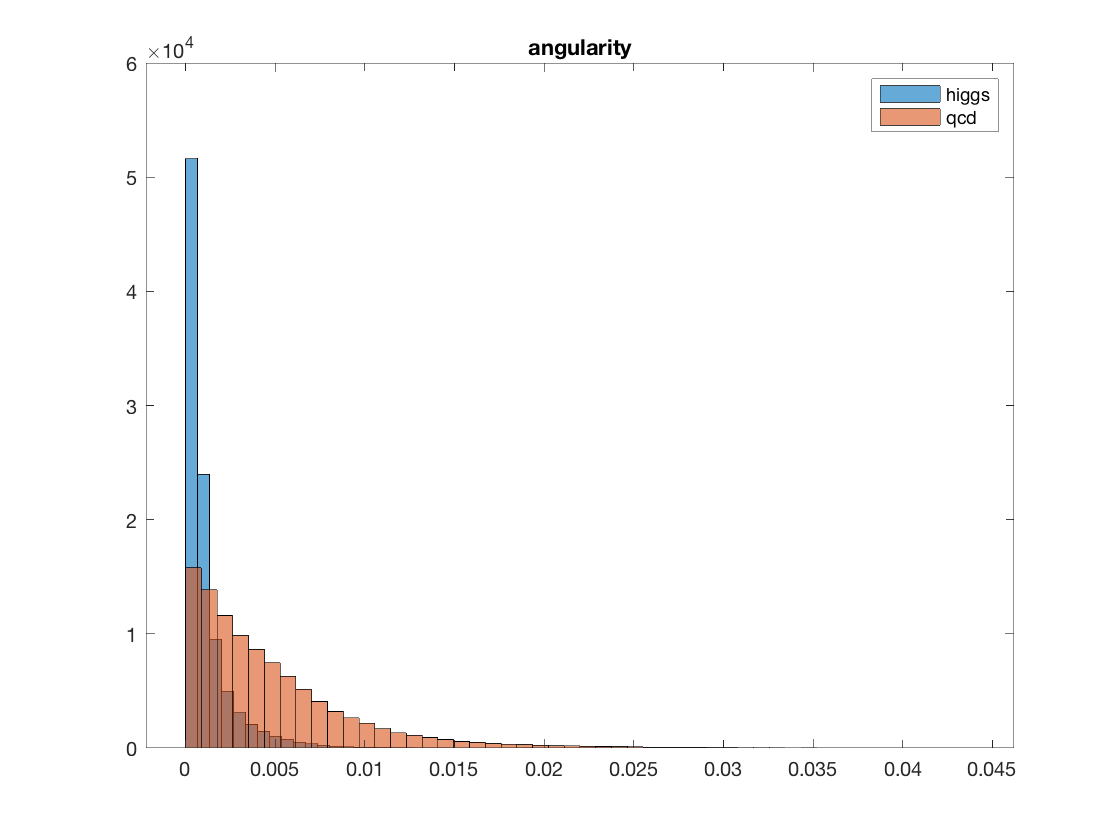

histogram(higgs(8,:),50)
hold on
histogram(qcd(8,:),50)
hold off
title('angularity')
legend('higgs','qcd')

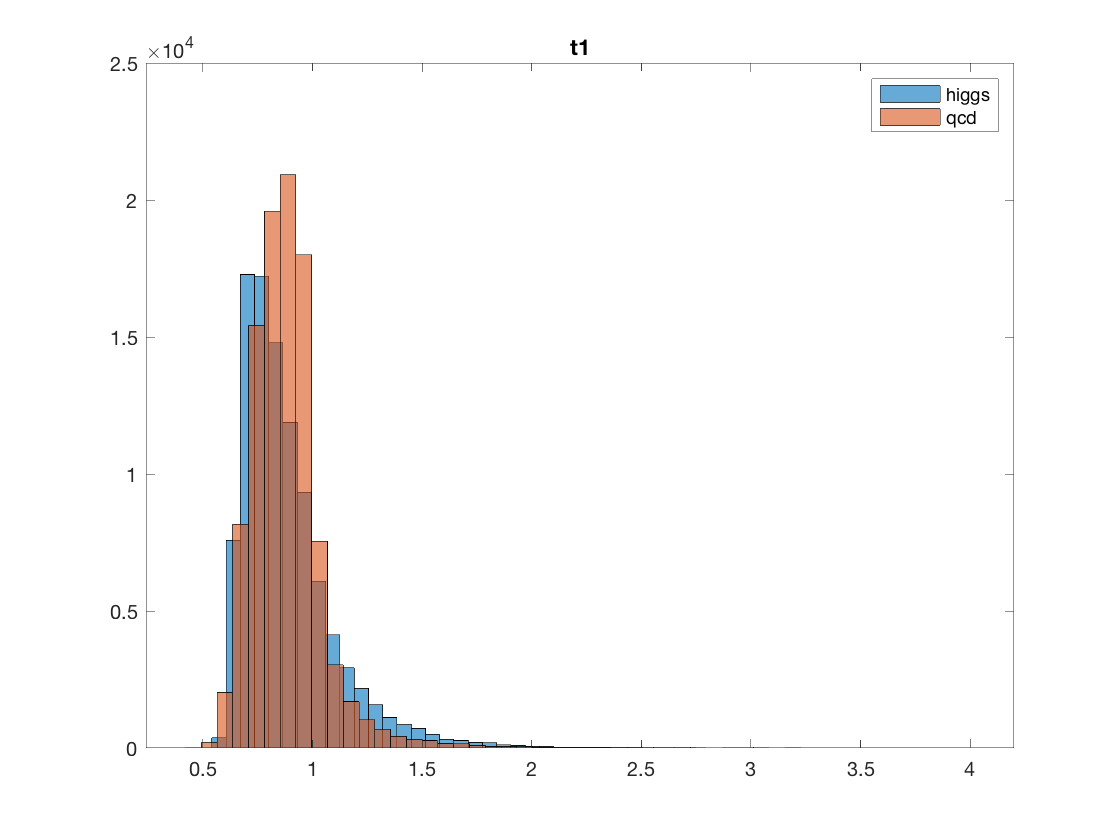

histogram(higgs(9,:),50)
hold on
histogram(qcd(9,:),50)
hold off
title('t1')
legend('higgs','qcd')

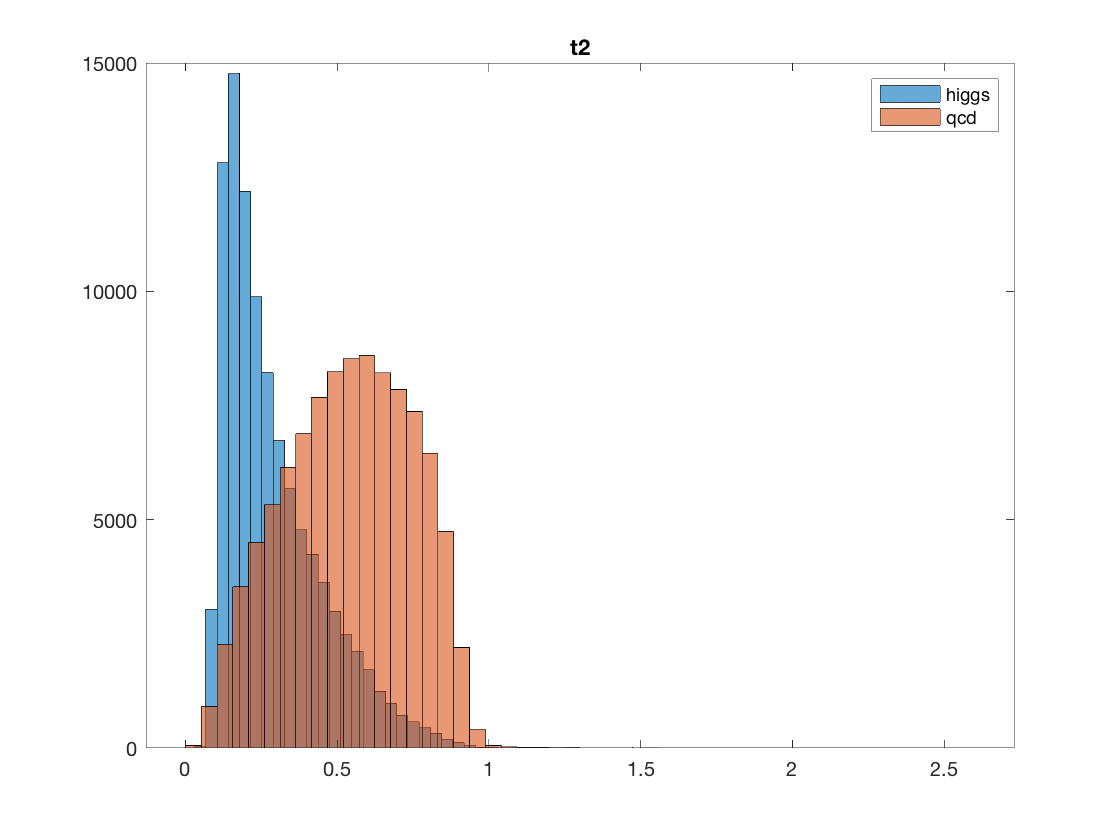

histogram(higgs(10,:),50)
hold on
histogram(qcd(10,:),50)
hold off
title('t2')
legend('higgs','qcd')

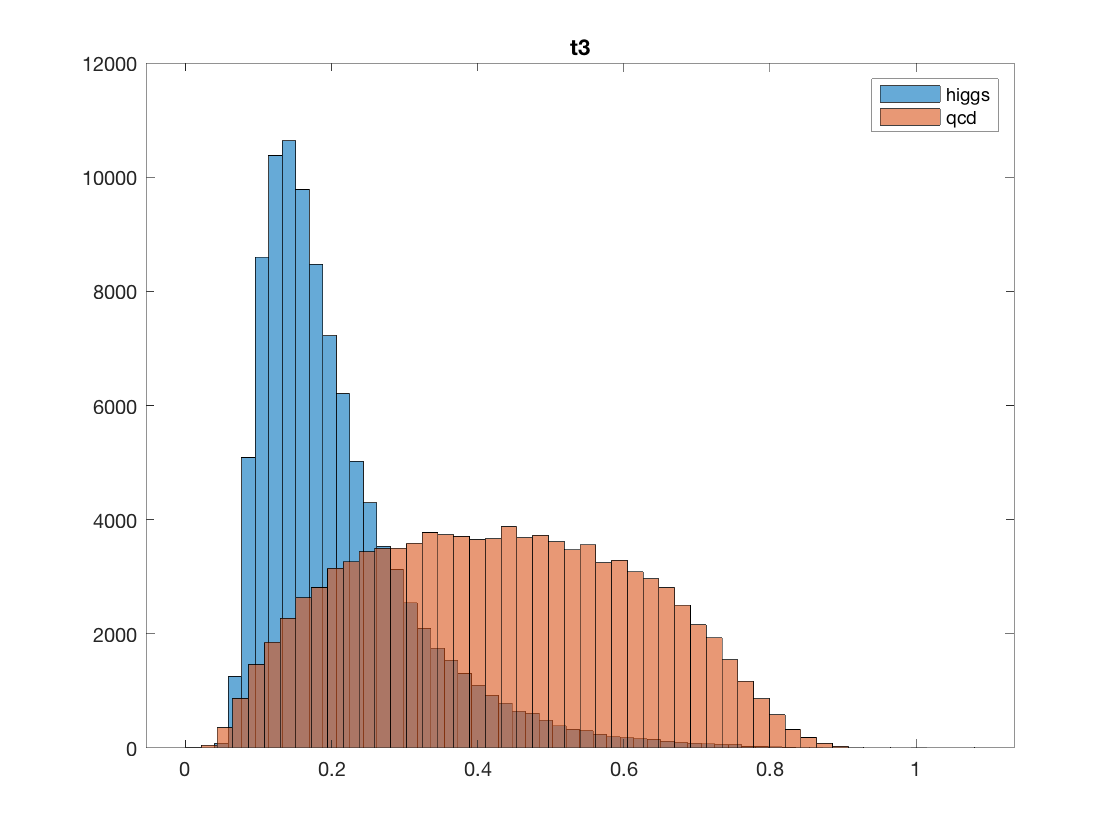

histogram(higgs(11,:),50)
hold on
histogram(qcd(11,:),50)
hold off
title('t3')
legend('higgs','qcd')

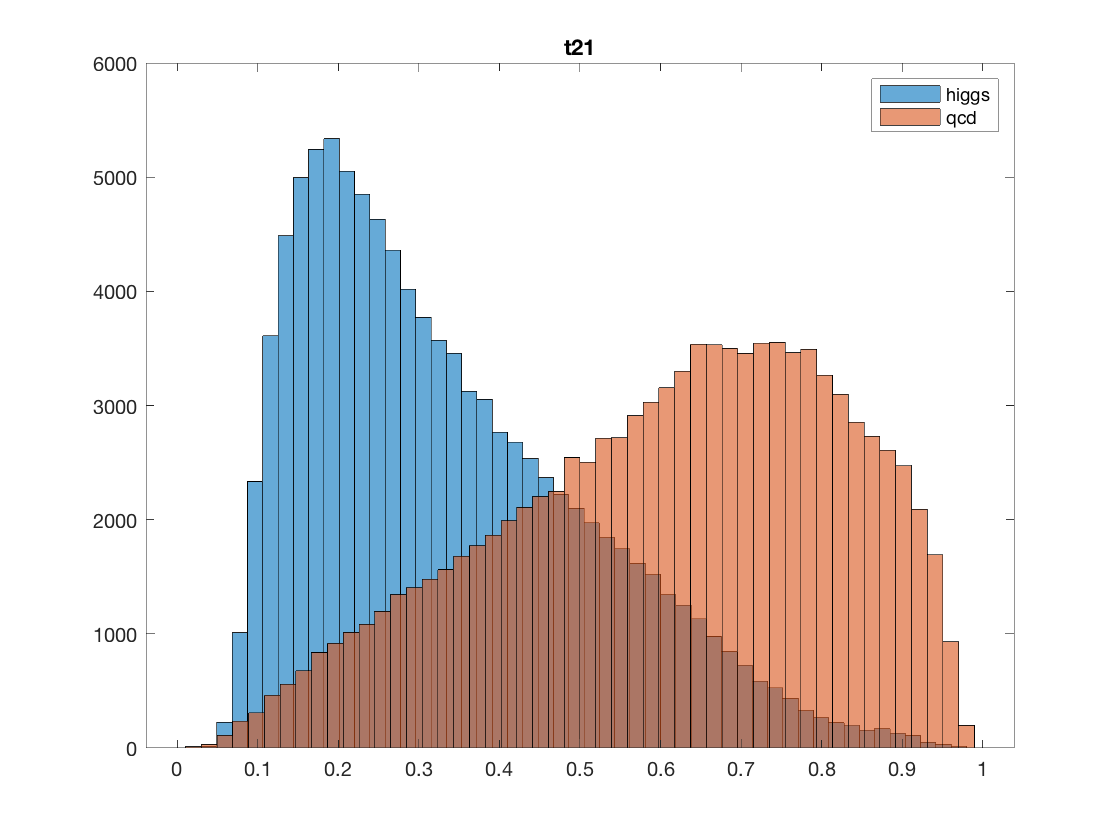

histogram(higgs(12,:),50)
hold on
histogram(qcd(12,:),50)
hold off
title('t21')
legend('higgs','qcd')

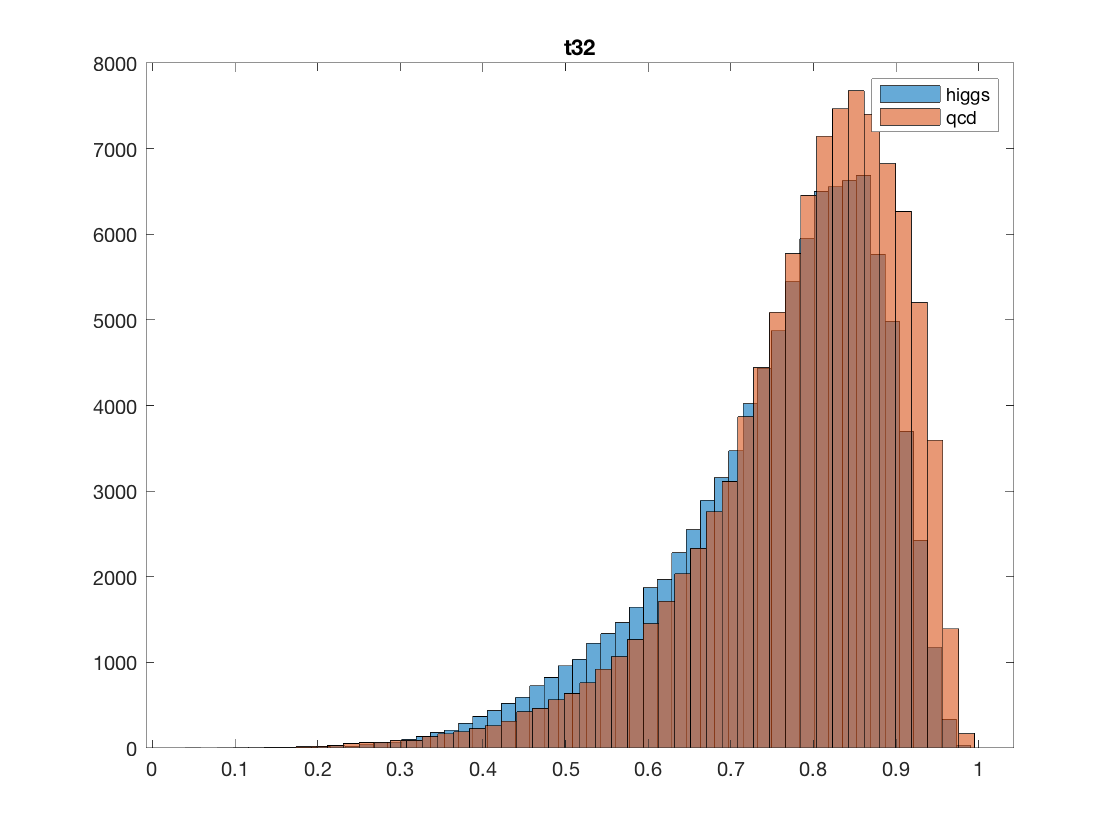

histogram(higgs(13,:),50)
hold on
histogram(qcd(13,:),50)
hold off
title('t32')
legend('higgs','qcd')

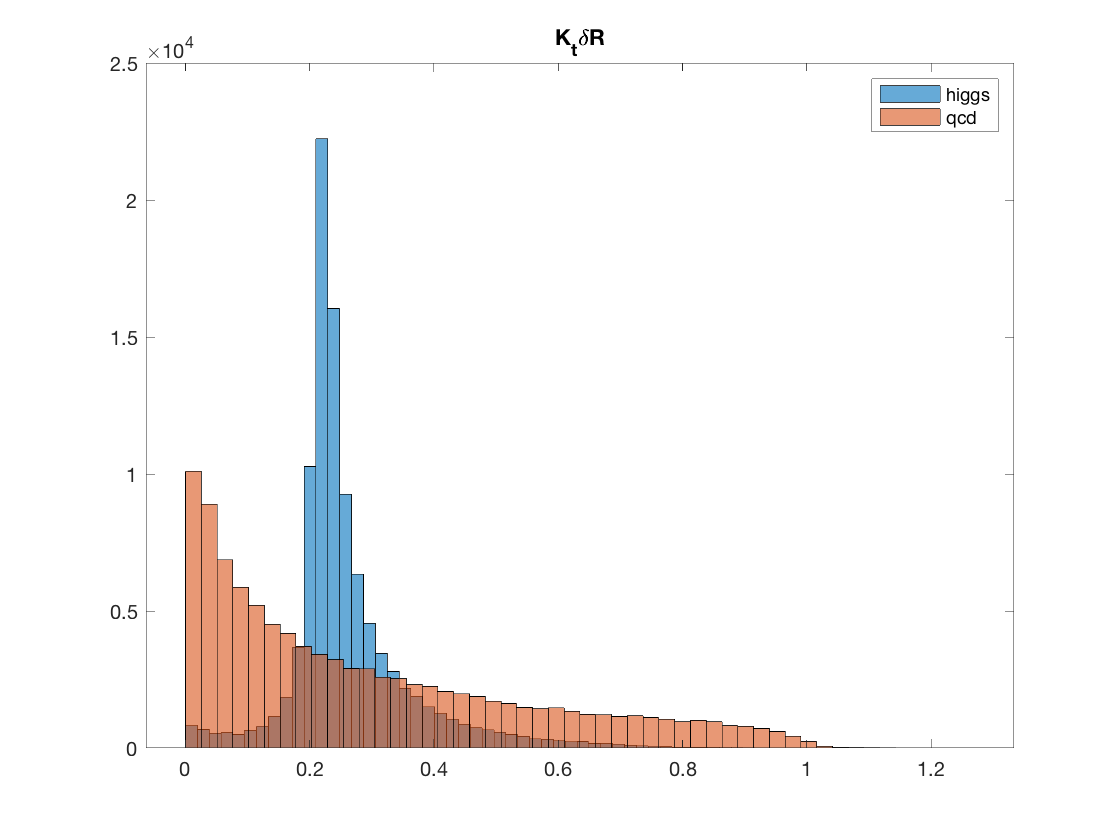

histogram(higgs(14,:),50)
hold on
histogram(qcd(14,:),50)
hold off
title('K_{t}\DeltaR')
legend('higgs','qcd')

According to the plots, ee2, t2,t3,t21, and KtDeltaR are the features that are descriminative. Among those features, KtDeltaR is about discriminative as the mass feature because the KtDeltaR distribution in Higgs data and QCD data has a very clear seperation. Therefore, the expected significance of KtDeltaR after the mass cut will be improved by a lot.

In this part, I am going to perform the mass cut on ktdeltaR feature. I will follow the exact same procedure I did when doing mass cut on the mass feature. I first fit the ktdeltaR feature in both QCD and Higgs data with a Poisson distribution. Then I find the cut that optimize $\frac{N_{\mathrm{Higgs}} }{\sqrt{N_{\mathrm{qcd}} }}$. 

The code below finds the cut that optimize the ratio.


ktdeltR_higgs = higgs(14,:);
ktdeltR_qcd = qcd(14,:);
lambda = mean(ktdeltR_higgs);
pd_14_higgs = fitdist(ktdeltR_higgs','Poisson');
pd_14_qcd = fitdist(ktdeltR_qcd','Poisson');

fun_14 = @(t) (50*(cdf(pd_14_higgs,lambda+t)-cdf(pd_14_higgs,lambda-t)))/sqrt(2000*(cdf(pd_14_qcd,lambda+t)-cdf(pd_14_qcd,lambda-t)));

ratio = fun_14(1/100);
for t =2:100
    
    diff = abs(fun_14(t/100)-ratio);
    ratio = fun_14(t/100);
    if diff<=0.001
        cut_14 = t/100;
        break
    end
end

After I run the code, it is found that when throwing away the data that is smaller than 0.26-0.28 and the data that is greater than 0.26+0.28. The ratio $\frac{N_{\mathrm{Higgs}} }{\sqrt{N_{\mathrm{qcd}} }}$ is optimized.